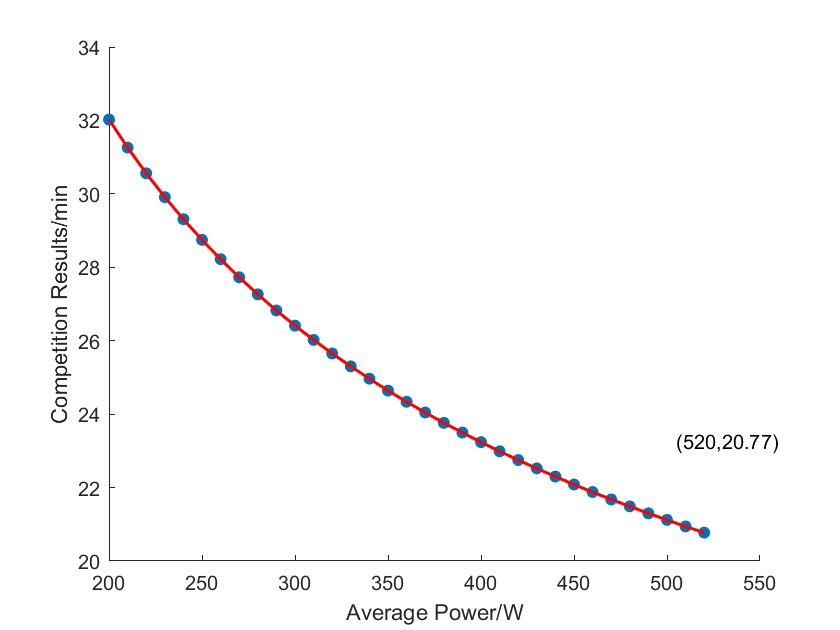

clear y
Mode.q2_2 = 0;
switch Mode.q2_2
    case 0
        treal=35*60+54+10/60;
        kp0=0.4;
        x1=log(mmt.z1);y1=log(gp.z1);
    case 1
        treal=36*60+05+10/60;
        kp0=0.2;
        x1=log(mmt.z2);y1=log(gp.z2);
end
d=0;
for P = 200:10:600
    d=d+1;
    P2 = P*kp0;
    n = 1;
    [ob]=polyfit(x1,y1,n);
    % syms x y
    % eqn=log(y)==ob(1)*(log(x))+ob(2);
    y=P;
    x=exp((log(y)-ob(2))/ob(1));
    t3 = test1(P2,L,treal);
    if t3<x
        l3=1;
    else l3=0;
    end
    board(d,:)=[P t3 x l3];
end
n = 1:sum(board(:,4));
figure
scatter(board(n,1),board(n,2)/60*1.3,'filled');hold on
plot(board(n,1),board(n,2)/60*1.3,'r','LineWidth',1.5)
xlabel('Average Power/W' );ylabel('Competition Results/min')
Pi = max(board(n,1)); 
ob=['(',num2str(Pi),',',num2str(roundn(min(board(n,2)/60*1.3),-2)),')'];
text(max(board(n,1))-15,min(board(n,2)/60*1.3+2.5),ob);

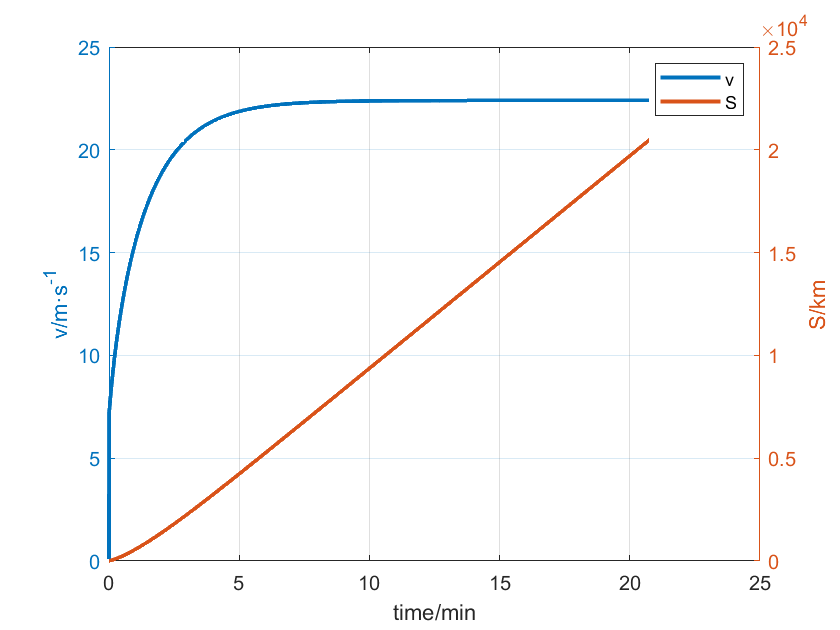


[ans v S t1]= test1(Pi*kp0,L,treal) ;
ti=(t1.a:t1.b:t1.end)/60*1.3;
figure;
[Y,H1,H2]=plotyy(ti,v,ti,S);
legend('v','S')
xlabel('time/min');
set(get(Y(1),'ylabel'),'string', 'v/m·s^{-1}');%,'fontsize',16
set(get(Y(2),'ylabel'),'string', 'S/km');
set(H1,'LineWidth',2 );%,'fontsize',16
set(H2,'LineWidth',2 );%,'fontsize',16
grid on;